% chenzhe, 2019-09-03
% It is likely useful to manually label twin-gb intersection.  We need some ground truth data anyway.


clear;
addChenFunction;

% grainDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab\Grain_1144_data_for_paper_ppt','Folder to save the grain data'),'\'];
dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');
dicFiles = dir([dicPath,'\*.mat']);
dicFiles = struct2cell(dicFiles);
dicFiles = dicFiles(1,:)';

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor','strainPauses');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab_after_realign','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\*.mat','select the results where twin identification was based on trace dir and strain');

[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\temp_results\*.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gDiameter','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gDiameter','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

% [data] strain data. Convert into v7.3 for partial loading
clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

D:\WE43_T6_C1_insitu_compression\stitched_DIC\_1


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_2


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_3


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_4


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_5


v7.3 file already exist



% (0) load data, using SF threshold values to assign active twin system, and make maps
% Load cluster number maps (cleaned).

clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []%iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');

% load previous twin_gb interaction result, for reference.
% load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));

[newVariantFile, newVariantFilePath] = uigetfile('D:\p\m\DIC_Analysis\temp_results\WE43_T6_C1_new_variant_map.mat','select the new result of dividing twin into variants');
load(fullfile(newVariantFilePath,newVariantFile),'struCell','trueTwinMapCell');

edge_gIDs = unique([reshape(ID(1,:),[],1); reshape(ID(end,:),[],1); ID(:,1); ID(:,end)]);

## Load data here.

(3)  We categorize the grain boundary into different groups, and look at how twinning activity is affected by the neighboring grains at these grain boundaries. 

The effect of high strain on twin growth/activation: 

For each grain and grain boundary, we calculate the mean of the effective strain of all data points at the same distance (d) to the grain boundary, for all distances d=1,2,3,...,250

And then for each category, we take all the grain and grain boundaries,  and take the mean of all the mean effective strains @ each distances to grain boundary 

So, we get a curve that represents the strain distribution w.r.t to distance to gb, for each category

--> If we have slip on one side of gb, and twinning on the otherside.  At the previous strain level, slip side strain was highest.

--> slip-slip, and slip side of slip-new twin pair, also tend to have high strain.

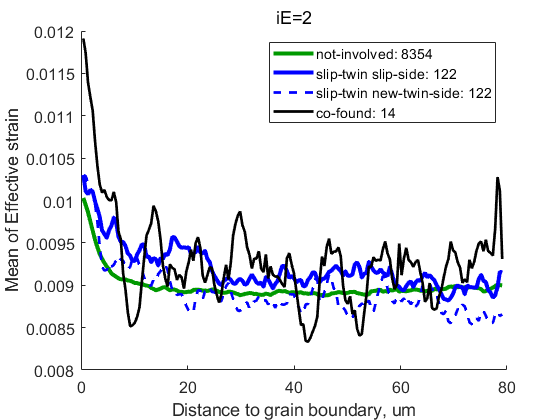

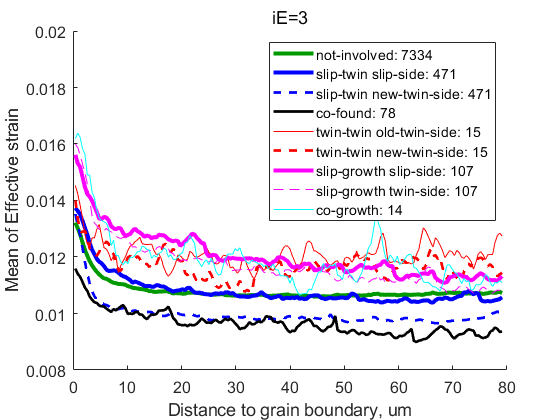

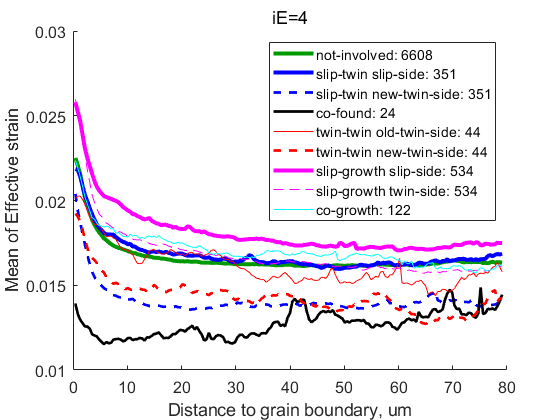

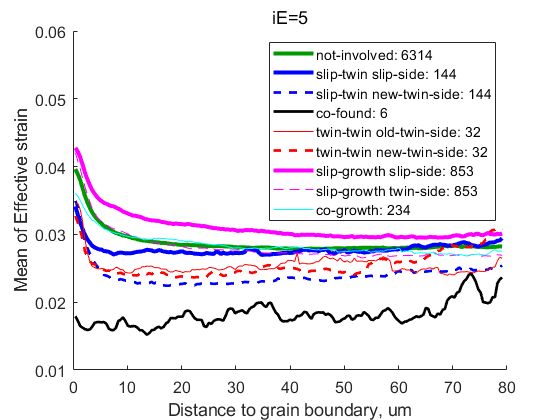

yLimits = [nan,nan];
yLimits = [NaN       NaN;
    0.008    0.012;
    0.008    0.02;
    0.010    0.03;
    0.010    0.06];

for iE = 2:5
    load(['D:\p\m\DIC_Analysis\temp_results\twin_gb_summary_',num2str(iE),'.mat']);
    
    um_per_dp = 5*360/4096;    % micron per data point, ~0.43
    nPts = 180; %length(x_dist);    % or 150
    % ndp_to_plot = 150;
    
    expr = ['edmat_',num2str(iE),';'];  % or 'edmatII_[iE]'
    edmat = evalin('base',expr);
    
    %% (1) nanmean
    clear eline_not_involved eline_slip_twin_a eline_slip_twin_b eline_co_found eline_twin_twin_a eline_twin_twin_b eline_slip_growth_a eline_slip_growth_b eline_co_growth
    legend_str = []; istr = 1;
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_not_involved, 'rows');
    eline_not_involved = nanmean(edmat(ind,4:end),1);
    legend_str{istr} = ['not-involved: ',num2str(sum(ind))]; istr = istr + 1; 
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_twin_a, 'rows');
    eline_slip_twin_a = nanmean(edmat(ind,4:end),1);
    legend_str{istr} = ['slip-twin slip-side: ',num2str(sum(ind))]; istr = istr + 1; 
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_twin_b, 'rows');
    eline_slip_twin_b = nanmean(edmat(ind,4:end),1);
    legend_str{istr} = ['slip-twin new-twin-side: ',num2str(sum(ind))]; istr = istr + 1; 
    
    [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_co_found, 'rows');
    eline_co_found = nanmean(edmat(ind,4:end),1);
    legend_str{istr} = ['co-found: ',num2str(sum(ind))]; istr = istr + 1; 
    try
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_twin_twin_a, 'rows');
        eline_twin_twin_a = nanmean(edmat(ind,4:end),1);
        legend_str{istr} = ['twin-twin old-twin-side: ',num2str(sum(ind))]; istr = istr + 1; 
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_twin_twin_b, 'rows');
        eline_twin_twin_b = nanmean(edmat(ind,4:end),1);
        legend_str{istr} = ['twin-twin new-twin-side: ',num2str(sum(ind))]; istr = istr + 1; 
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_growth_a, 'rows');
        eline_slip_growth_a = nanmean(edmat(ind,4:end),1);
        legend_str{istr} = ['slip-growth slip-side: ',num2str(sum(ind))]; istr = istr + 1; 
        
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_growth_b, 'rows');
        eline_slip_growth_b = nanmean(edmat(ind,4:end),1);
        legend_str{istr} = ['slip-growth twin-side: ',num2str(sum(ind))]; istr = istr + 1; 
         
        [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_co_growth, 'rows');
        eline_co_growth = nanmean(edmat(ind,4:end),1);
        legend_str{istr} = ['co-growth: ',num2str(sum(ind))]; istr = istr + 1; 
    end
    figure;disableDefaultInteractivity(gca); hold on;
    plot(um_per_dp*x_dist(1:nPts),eline_not_involved(1:nPts),'-','color',[0 0.6 0],'LineWidth',3);
    plot(um_per_dp*x_dist(1:nPts),eline_slip_twin_a(1:nPts),'-b','LineWidth',3);
    plot(um_per_dp*x_dist(1:nPts),eline_slip_twin_b(1:nPts),'--b','LineWidth',2);
    
    plot(um_per_dp*x_dist(1:nPts),eline_co_found(1:nPts),'-k','LineWidth',2);
    try
        plot(um_per_dp*x_dist(1:nPts),eline_twin_twin_a(1:nPts),'-r','LineWidth',.5);
        plot(um_per_dp*x_dist(1:nPts),eline_twin_twin_b(1:nPts),'--r','LineWidth',2);
        
        plot(um_per_dp*x_dist(1:nPts),eline_slip_growth_a(1:nPts),'-m','LineWidth',3);
        plot(um_per_dp*x_dist(1:nPts),eline_slip_growth_b(1:nPts),'--m','LineWidth',.5);
        plot(um_per_dp*x_dist(1:nPts),eline_co_growth(1:nPts),'-c','LineWidth',.5);
    end
    % legend({'non-involved','slip-twin slip-side','slip-twin new-twin-side', 'co-found','twin-twin old-twin-side','twin-twin new-twin-side', 'slip-growth slip-side','slip-growth twin-side','co-growth'});
    legend(legend_str);
    set(gca,'fontsize',12,'ylim',yLimits(iE,:));
    xlabel('Distance to grain boundary, um');
    ylabel('Mean of Effective strain');
    
    title(['iE=',num2str(iE)],'fontweight','normal');
    yLimits(iE,:) = get(gca,'YLim');
    
%     %% (2) median
%     clear eline_not_involved eline_slip_twin_a eline_slip_twin_b eline_co_found eline_twin_twin_a eline_twin_twin_b eline_slip_growth_a eline_slip_growth_b eline_co_growth
%     legend_str = []; istr = 1;
%     
%     [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_not_involved, 'rows');
%     eline_not_involved = median(edmat(ind,4:end),1,'omitnan');
%     legend_str{istr} = ['not-involved: ',num2str(sum(ind))]; istr = istr + 1; 
%     
%     [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_twin_a, 'rows');
%     eline_slip_twin_a = median(edmat(ind,4:end),1,'omitnan');
%     legend_str{istr} = ['slip-twin slip-side: ',num2str(sum(ind))]; istr = istr + 1; 
%     
%     [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_twin_b, 'rows');
%     eline_slip_twin_b = median(edmat(ind,4:end),1,'omitnan');
%     legend_str{istr} = ['slip-twin new-twin-side: ',num2str(sum(ind))]; istr = istr + 1; 
%     
%     [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_co_found, 'rows');
%     eline_co_found = median(edmat(ind,4:end),1,'omitnan');
%     legend_str{istr} = ['co-found: ',num2str(sum(ind))]; istr = istr + 1; 
%     try
% %         [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_twin_twin_a, 'rows');
% %         eline_twin_twin_a = median(edmat(ind,4:end),1,'omitnan');
% %         legend_str{istr} = ['twin-twin old-twin-side: ',num2str(sum(ind))]; istr = istr + 1; 
%         
%         [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_twin_twin_b, 'rows');
%         eline_twin_twin_b = median(edmat(ind,4:end),1,'omitnan');
%         legend_str{istr} = ['twin-twin new-twin-side: ',num2str(sum(ind))]; istr = istr + 1; 
%         
%         [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_growth_a, 'rows');
%         eline_slip_growth_a = median(edmat(ind,4:end),1,'omitnan');
%         legend_str{istr} = ['slip-growth slip-side: ',num2str(sum(ind))]; istr = istr + 1; 
%         
% %         [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_slip_growth_b, 'rows');
% %         eline_slip_growth_b = median(edmat(ind,4:end),1,'omitnan');
% %         legend_str{istr} = ['slip-growth twin-side: ',num2str(sum(ind))]; istr = istr + 1; 
%         
% %         [ind,~] = ismember([edmat(:,3),edmat(:,2)], bg_co_growth, 'rows');
% %         eline_co_growth = median(edmat(ind,4:end),1,'omitnan');
% %         legend_str{istr} = ['co-growth: ',num2str(sum(ind))]; istr = istr + 1; 
%     end
%     
%     figure;disableDefaultInteractivity(gca); hold on;
%     nPts = length(x_dist);    % or 150
%     % ndp_to_plot = 150;
%     plot(x_dist(1:nPts),eline_not_involved(1:nPts),'-','color',[0 0.6 0],'LineWidth',3);
%     plot(x_dist(1:nPts),eline_slip_twin_a(1:nPts),'-b','LineWidth',3);
%     plot(x_dist(1:nPts),eline_slip_twin_b(1:nPts),'--b','LineWidth',2);
%     
%     plot(x_dist(1:nPts),eline_co_found(1:nPts),'-k','LineWidth',2);
%     try
% %         plot(x_dist(1:nPts),eline_twin_twin_a(1:nPts),'-r','LineWidth',.5);
%         plot(x_dist(1:nPts),eline_twin_twin_b(1:nPts),'--r','LineWidth',2);
%         
%         plot(x_dist(1:nPts),eline_slip_growth_a(1:nPts),'-m','LineWidth',3);
% %         plot(x_dist(1:nPts),eline_slip_growth_b(1:nPts),'--m','LineWidth',.5);
% %         plot(x_dist(1:nPts),eline_co_growth(1:nPts),'-c','LineWidth',.5);
%     end
%     % legend({'non-involved','slip-twin slip-side','slip-twin new-twin-side', 'co-found','twin-twin old-twin-side','twin-twin new-twin-side', 'slip-growth slip-side','slip-growth twin-side','co-growth'});
%     legend(legend_str);
%     set(gca,'fontsize',12);
%     xlabel('Distance to grain boundary');
%     ylabel('Medium of Effective strain');
% 
%     title(['iE=',num2str(iE)],'fontweight','normal');

end

**The second method of calculating strain distrubtion: each data point only contribute to/affected by its closest grain boundary.  The trend is similar, but data is more noisy.  So, no plot here.**

## Summary. To determine twin activation, effect of (1) m' rank, (2) m', (3) resB, (4) resB rank

Objects to compare: twinned variants in twinned grains (1) All twin boundaries (2) Boundaries with intersecting twins (3) Boundaries where twins are considered to be initiated from Properties to compare: (1) m', (2) m' rank, (3) resB, (4) resB rank

iE = 5;
load(['D:\p\m\DIC_Analysis\temp_results\twin_gb_summary_',num2str(iE),'.mat']);

## **Summarize some distribution, e.g., grain size, gb_length, etc**

**Distribution of gb length?**

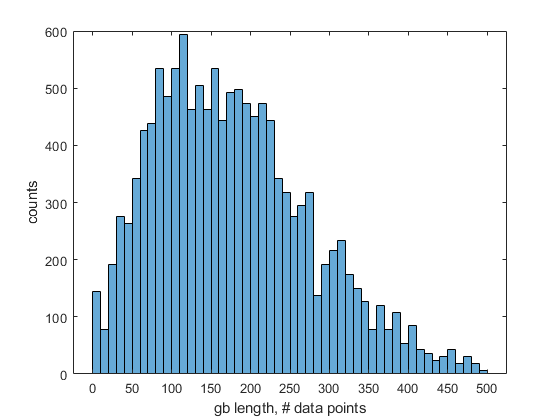

figure;
histogram(T.gb_length, 0:10:500);
xlabel('gb length, # data points');
ylabel('counts');

ind = (T.gb_length > 20);

**Distribution of grain diameter**

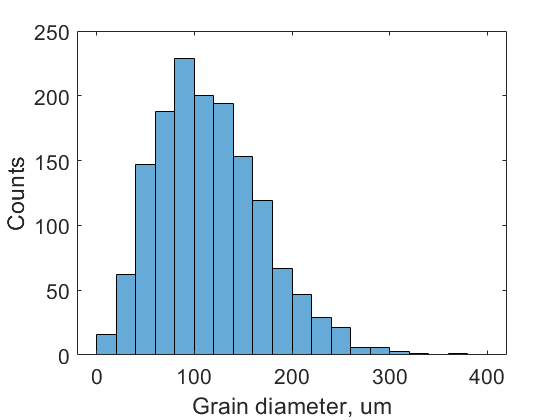

gs = [];
for iS = 1:length(struCell{2})
    ID_current = struCell{2}(iS).gID;
    ind = find(gID==ID_current);
    gs = [gs; sqrt((struCell{2}(iS).gVol * umPerPtDIC.^2)*4/pi)];
end
figure;
histogram(gs,0:20:400);
xlabel('Grain diameter, um');
ylabel('Counts');
set(gca,'fontsize',16)

## **To study the effect of m', m'-rank, etc.  Note how we should define TT, the background distribution.**

iE = 5;
load(['D:\p\m\DIC_Analysis\temp_results\twin_gb_summary_',num2str(iE),'.mat'], 'T', 'T2', 'struCell');

TT = [T;T2];

**(I) Effect of m'-factor.  Compared <active variants> vs. <all possible variants>  **

**The following generates and compares the probability mass distribution, This just means that the active variants has more with high m', and less with small m'. **

disp('(1) Effect of m'' factor ===============');

(1) Effect of m' factor ===============


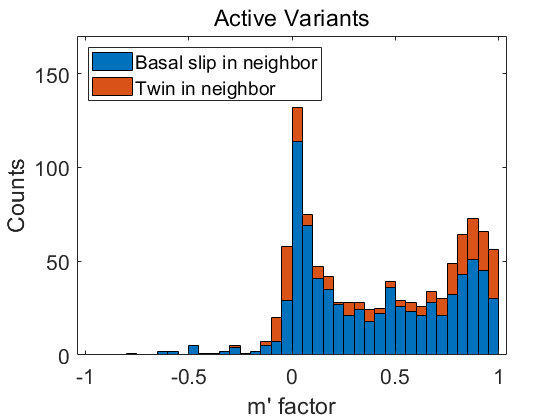

% close all;
edges = [0-1:0.05:0.95, 1+1000*eps];
xpos = 0.025-1:0.05:0.975;

% (1) If look at all the active variants.  
% ind = T.incoming==1;    
ind = (T.iiE_each_twin_at_this_boundary == T.iiE_each_twin)&(T.iiE_each_twin<=iE);    
% ind = (T.iiE_each_twin_at_this_boundary == T.iiE_each_twin)&(T.iiE_each_twin<=iE)&(~ismember(T.ID,edge_gIDs))&(~ismember(T.ID_neighbor,edge_gIDs));  
% ind = (T.initiating==1);    
t = T(ind,:);
% figure; histogram(t.mPrime, 0:0.05:1);
% xlabel('m'' wrt active ss/ts in neighbor');
% ylabel('Counts');
% title('for active variants at the initiating boundary','fontweight','normal');
N = histcounts(t.mPrime, edges);


% When the active mode in neighbor is basal
ind1 = ind&(ismember(T.ssn_nb,[1,2,3]));
t = T(ind1,:);
N1 = histcounts(t.mPrime, edges);
% When the active mode in neighbor is twin
ind2 = ind&(ismember(T.ssn_nb,[19:24]));
t = T(ind2,:);
N2 = histcounts(t.mPrime, edges);

figure; disableDefaultInteractivity(gca);
bar(xpos, [N1(:),N2(:)], 1, 'stacked');
legend({'Basal slip in neighbor','Twin in neighbor'},'location','northwest');
set(gca,'fontsize',16,'ylim',[0 170]);
xlabel('m'' factor');
ylabel('Counts');
title('Active Variants','fontweight','normal');

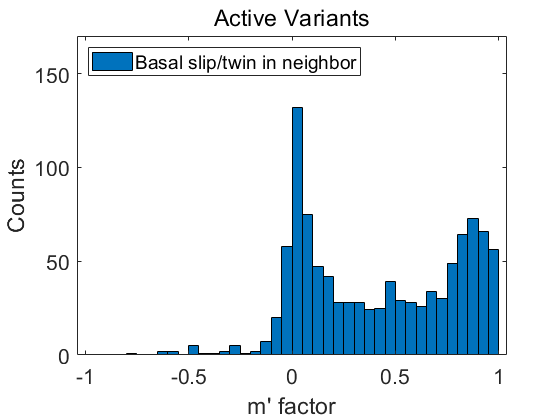


figure; disableDefaultInteractivity(gca);
bar(xpos, [N1(:)+N2(:)], 1, 'stacked');
legend({'Basal slip/twin in neighbor'},'location','northwest');
set(gca,'fontsize',16,'ylim',[0 170]);
xlabel('m'' factor');
ylabel('Counts');
title('Active Variants','fontweight','normal');


% ((())) just those with basal in neighbor
% figure; disableDefaultInteractivity(gca);
% bar(xpos, [N1(:)], 1, 'stacked');
% legend({'Basal in neighbor'},'location','north');
% set(gca,'fontsize',16,'ylim',[0 150]);
% xlabel('m'' factor');
% ylabel('Counts');
% title('Active variants','fontweight','normal');

% ((())) Just those with twin in neighbor 
% figure; disableDefaultInteractivity(gca);
% bar(xpos, [N2(:)], 1, 'stacked');
% legend({'Twin in neighbor'},'location','north');
% set(gca,'fontsize',16,'ylim',[0 60]);
% xlabel('m'' factor');
% ylabel('Counts');
% title('Active variants','fontweight','normal');

pmf_all_exp = (N1+N2)./sum([N1(:);N2(:)]);  % probability mass function
pmf_basal_exp = N1./sum(N1(:));  % probability mass function, for active variants interacting with neighbor's basal   
pmf_twin_exp = N2./sum(N2(:));  % probability mass function, for active variants interacting with neighbor's twin  
% yyaxis right;
% plot(xpos,pmf,'-ok')


% The follwing are the baseline/background
% (2) For: all the possible variants, in all the twinned grains, look at their m' wrt all neighbor grains' MOST POSSIBLE basal         
% N3 = histcounts(TT.mPrime_wrtB, edges);
% figure; disableDefaultInteractivity(gca);
% bar(xpos, [N3(:)], 1, 'stacked');
% legend({'Basal in neighbor'},'location','north');
% set(gca,'fontsize',16,'ylim',[0 7000]);
% xlabel('m'' factor');
% ylabel('Counts');
% title('All possible variants','fontweight','normal');
% pmf_basal = N3./sum(N3);

% (3) For: all the possible variants, in all the twinned grains, look at their m' wrt all neighbor grains' MOST POSSIBLE twin   
% N4 = histcounts(TT.mPrime_wrtT, edges);
% figure; disableDefaultInteractivity(gca);
% bar(xpos, [N4(:)], 1, 'stacked');
% legend({'Twin in neighbor'},'location','north');
% set(gca,'fontsize',16,'ylim',[0 5000]);
% xlabel('m'' factor');
% ylabel('Counts');
% title('All possible variants','fontweight','normal');
% pmf_twin = N4./sum(N4);

% (5) relative strength, basal slip in neighbor
% figure; disableDefaultInteractivity(gca); hold on;
% plot(xpos, pmf_basal_exp, '-ko','linewidth',1.5);
% plot(xpos, pmf_basal, '--kd','linewidth',1.5);
% ylabel('Probability distribution');
% yyaxis right;
% plot(xpos, pmf_basal_exp./pmf_basal, '-ro','linewidth',1.5);
% set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1]);
% xlabel('m'' factor');
% ylabel('Multiples of random');
% set(gca,'fontsize',16);
% legend({'Active variants','All possible variants','Ratio'},'location','north');
% title('Basal in neighbor', 'fontweight','normal');

% (6) relative strength, twin in neighbor
% figure; disableDefaultInteractivity(gca); hold on;
% plot(xpos, pmf_twin_exp, '-ko','linewidth',1.5);
% plot(xpos, pmf_twin, '--kd','linewidth',1.5);
% ylabel('Probability distribution');
% yyaxis right;
% plot(xpos, pmf_twin_exp./pmf_twin, '-ro','linewidth',1.5);
% set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1]);
% ylabel('Multiples of random');
% xlabel('m'' factor');
% set(gca,'fontsize',16);
% legend({'Active variants','All possible variants','Ratio'},'location','north');
% title('Twin in neighbor', 'fontweight','normal');

% Distribution of m' wrt most likely basal vs. most likely twin
% figure;
% plot(TT.mPrime_wrtB, TT.mPrime_wrtT,'.');
% xlabel('wrt basal');
% ylabel('wrt twin');

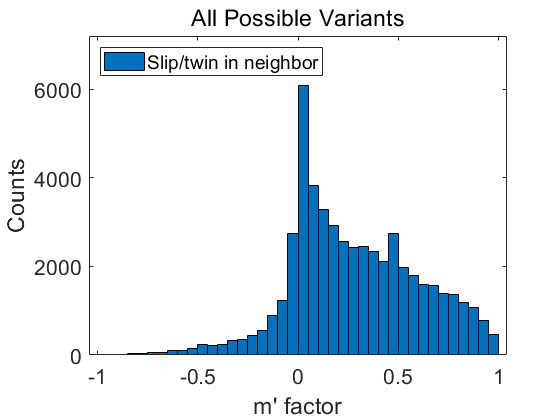


% (7) For: all the possible variants, look at their m' wrt all neighbor grains' MOST POSSIBLE slip or twin   
N5 = histcounts(TT.mPrime, edges);
figure; disableDefaultInteractivity(gca); 
bar(xpos, [N5(:)], 1, 'stacked');
legend({'Slip/twin in neighbor'},'location','northwest');
set(gca,'fontsize',16,'ylim',[0 7200]);
xlabel('m'' factor');
ylabel('Counts');
title('All Possible Variants','fontweight','normal');

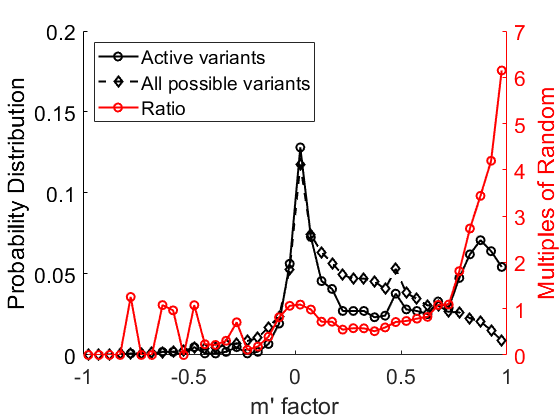

pmf_all = N5./sum(N5);

% (8) relative strength, slip/twin in neighbor
figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_all_exp, '-ko','linewidth',1.5);
plot(xpos, pmf_all, '--kd','linewidth',1.5);
set(gca,'ylim',[0 0.2]);
ylabel('Probability Distribution');
yyaxis right;
plot(xpos, pmf_all_exp./pmf_all, '-ro','linewidth',1.5);
set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1]);
ylabel('Multiples of Random');
xlabel('m'' factor');
set(gca,'fontsize',16);
legend({'Active variants','All possible variants','Ratio'},'location','northwest');
title('');


% ((())) If only select the twin system of interest with SF > 0.3
% For mPrime with both TorB in neighbor, there were already some assumptions, such as SF>0.2, SF_normalized>0.8, exist before twin of interest.
% ind = (TT.TSF>0.3)&((TT.iiE_twins_at_this_boundary_nb<TT.iiE_each_twin_at_this_boundary)|(TT.iiE_twins_at_this_boundary_nb==inf));   
ind = (T2.TSF>0.3);   % If we select possible twin systems to be with TSF > 0.3.
tt = [T;T2(ind,:)];

disp("============consider SF>0.3============")

============consider SF>0.3============


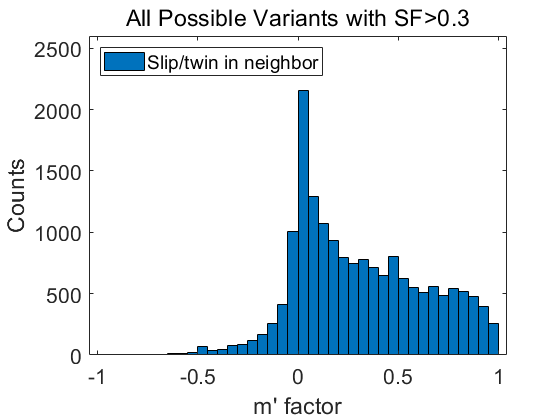

% (9) A restricted background
N6 = histcounts(tt.mPrime, edges);
figure; disableDefaultInteractivity(gca); 
bar(xpos, [N6(:)], 1, 'stacked');
legend({'Slip/twin in neighbor'},'location','northwest');
set(gca,'fontsize',16,'ylim',[0 2600]);
xlabel('m'' factor');
ylabel('Counts');
title('All Possible Variants with SF>0.3','fontweight','normal');

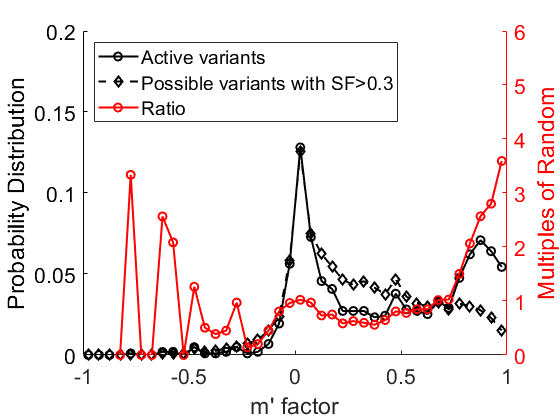

pmf_all_r = N6./sum(N6);

% (10) relative strength, slip/twin in neighbor
figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_all_exp, '-ko','linewidth',1.5);
plot(xpos, pmf_all_r, '--kd','linewidth',1.5);
set(gca,'ylim',[0 0.2]);
ylabel('Probability Distribution');
yyaxis right;
plot(xpos, pmf_all_exp./pmf_all_r, '-ro','linewidth',1.5);
set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1.5]);
ylabel('Multiples of Random');
xlabel('m'' factor');
set(gca,'fontsize',16);
legend({'Active variants','Possible variants with SF>0.3','Ratio'},'location','northwest');

% title('Twin in neighbor', 'fontweight','normal');


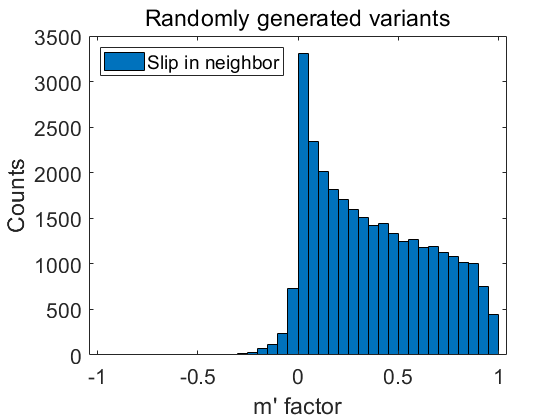

% calculate distribution of m' factor for random samples
edges = [0-1:0.05:0.95, 1+1000*eps];
xpos = 0.025-1:0.05:0.975;
mPrime = [];
for ii=1:5000
   euler_1 = random_euler;
   euler_2 = random_euler;
   
   [schmidFactorG1, schmidFactorG2, mPrimeMatrix, resBurgersMatrix, mPrimeMatrixAbs, resBurgersMatrixAbs] ...
       = calculate_mPrime_and_resB(euler_1, euler_2, [-1 0 0; 0 0 0; 0 0 0], [1 0 0], 'Mg', 'twin');
                        
   mPrime_local = mPrimeMatrix(19:24, 1:3);
   [mPrime_each_twin, ind] = max(mPrime_local,[],2);
   mPrime = [mPrime;mPrime_each_twin];
end
N7 = histcounts(mPrime, edges);
figure; disableDefaultInteractivity(gca); 
bar(xpos, [N7(:)], 1, 'stacked');
legend({'Slip in neighbor'},'location','northwest');
set(gca,'fontsize',16);
xlabel('m'' factor');
ylabel('Counts');
title('Randomly generated variants','fontweight','normal');

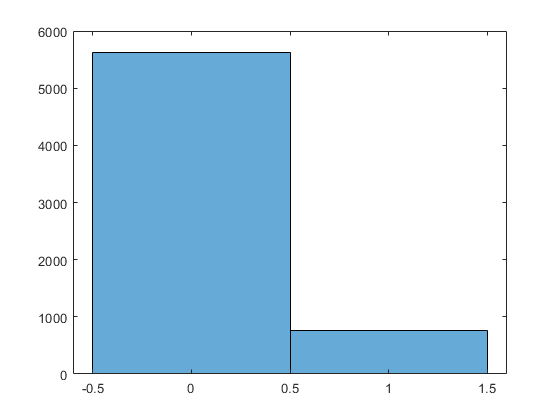

% So, if select the high variant_SF, low neighbor basal_SF ones, How
% effective is m' as a predictor?

ind = (T.max_basal_SF<0.3)&(T.max_twin_SF>0.3)&(T.max_basal_SF_nb>0.3)&(T.max_twin_SF_nb<0.3);
t = T(ind,:);
figure;
histogram(t.incoming)

**(II) Similarly, effect of m'-rank.**

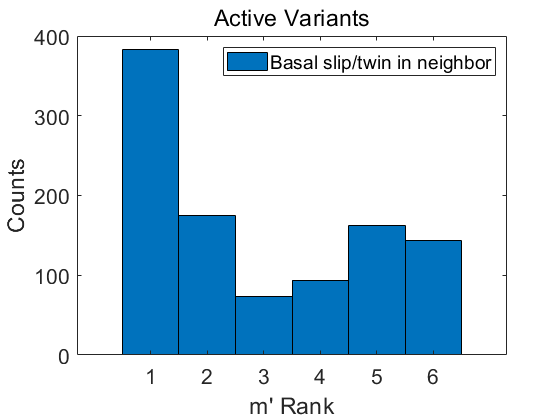

% close all;
edges = [0.5:1:6.5];
xpos = 1:6;

% (1) If look at all the active variants.  
ind = T.incoming==1;
ind = (T.iiE_each_twin_at_this_boundary == T.iiE_each_twin)&(T.iiE_each_twin<=iE);  
t = T(ind,:);
% figure; histogram(t.rank_mPrime);
% xlabel('m''-rank wrt active ss/ts in neighbor');
% ylabel('Counts');
% title('for active variants at the initiating boundary','fontweight','normal');
N = histcounts(t.rank_mPrime, edges);

figure; disableDefaultInteractivity(gca);  
bar(xpos, [N(:)], 1, 'stacked');
legend({'Basal slip/twin in neighbor'},'location','northeast');
set(gca,'fontsize',16);
xlabel('m'' Rank');
ylabel('Counts');
title('Active Variants','fontweight','normal');


% When the active mode in neighbor is basal
ind1 = ind&(ismember(T.ssn_nb,[1,2,3]));
t = T(ind1,:);
N1 = histcounts(t.rank_mPrime, edges);
% When the active mode in neighbor is twin
ind2 = ind&(ismember(T.ssn_nb,[19:24]));
t = T(ind2,:);
N2 = histcounts(t.rank_mPrime, edges);
% figure; disableDefaultInteractivity(gca);  
% bar(xpos, [N1(:),N2(:)], 1, 'stacked');
% legend({'Basal slip in neighbor','Twin in neighbor'},'location','northeast');
% set(gca,'fontsize',16);
% xlabel('m'' rank');
% ylabel('Counts');
% title('All active variants','fontweight','normal');

% figure; disableDefaultInteractivity(gca);  
% bar(xpos, [N1(:)], 1, 'stacked');
% legend({'Basal slip in neighbor'},'location','northeast');
% set(gca,'fontsize',16);
% xlabel('m'' rank');
% ylabel('Counts');
% title('Active variants','fontweight','normal');

% figure; disableDefaultInteractivity(gca);  
% bar(xpos, [N2(:)], 1, 'stacked');
% legend({'Twin in neighbor'},'location','northeast');
% set(gca,'fontsize',16);
% xlabel('m'' rank');
% ylabel('Counts');
% title('Active variants','fontweight','normal');

pmf_all_exp = (N1+N2)./sum([N1(:);N2(:)]);  % probability mass function
pmf_basal_exp = N1./sum(N1(:));  % probability mass function, for active variants interacting with neighbor's basal   
pmf_twin_exp = N2./sum(N2(:));  % probability mass function, for active variants interacting with neighbor's twin  
% yyaxis right;
% plot(xpos,pmf,'-ok')


% The follwing are the baseline/background.  Rank-1 has more, which is an artifact.   
% (2) For: all the possible variants, in all the twinned grains, look at their m' wrt all neighbor grains' MOST POSSIBLE basal         
N3 = histcounts(TT.rank_mPrime_wrtB, edges);
% figure; disableDefaultInteractivity(gca);  
% bar(xpos, [N3(:)], 1, 'stacked');
% legend({'Basal in neighbor'},'location','northeast');
% set(gca,'fontsize',16,'ylim',[0 11000]);
% xlabel('m'' rank');
% ylabel('Counts');
% title('All possible variants','fontweight','normal');
pmf_basal = N3./sum(N3);

% (3) For: all the possible variants, in all the twinned grains, look at their m' wrt all neighbor grains' MOST POSSIBLE twin   
N4 = histcounts(TT.rank_mPrime_wrtT, edges);
% figure; disableDefaultInteractivity(gca);  
% bar(xpos, [N4(:)], 1, 'stacked');
% legend({'Twin in neighbor'},'location','northeast');
% set(gca,'fontsize',16,'ylim',[0 11000]);
% xlabel('m'' rank');
% ylabel('Counts');
% title('All possible variants','fontweight','normal');
pmf_twin = N4./sum(N4);


% (4) Relative strength, all active wrt both basal and twin, vs. all possible wrt basal slip in neighbor     
% figure; hold on;
% plot(xpos, pmf_all_exp, '-ko','linewidth',1.5);
% plot(xpos, pmf_basal, '--kd','linewidth',1.5);
% ylabel('Probability distribution');
% yyaxis right;
% plot(xpos, pmf_all_exp./pmf_basal, '-ro','linewidth',1.5);
% set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1]);
% xlabel('m'' rank');
% ylabel('Multiples of random');
% set(gca,'fontsize',16);
% legend({'Active variants, ','All possible variants, basal in neighbor','Ratio'},'location','north');
% title('relative strength, all vs. basal', 'fontweight','normal');

% (5) relative strength, basal slip in neighbor
% figure; disableDefaultInteractivity(gca); hold on;
% plot(xpos, pmf_basal_exp, '-ko','linewidth',1.5);
% plot(xpos, pmf_basal, '--kd','linewidth',1.5);
% ylabel('Probability distribution');
% yyaxis right;
% plot(xpos, pmf_basal_exp./pmf_basal, '-ro','linewidth',1.5);
% set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1]);
% xlabel('m'' rank');
% ylabel('Multiples of random');
% set(gca,'fontsize',16);
% legend({'Active variants','All possible variants','Ratio'},'location','north');
% title('Basal in neighbor', 'fontweight','normal');

% (6) relative strength, twin in neighbor
% figure; disableDefaultInteractivity(gca); hold on;
% plot(xpos, pmf_twin_exp, '-ko','linewidth',1.5);
% plot(xpos, pmf_twin, '--kd','linewidth',1.5);
% ylabel('Probability distribution');
% yyaxis right;
% plot(xpos, pmf_twin_exp./pmf_twin, '-ro','linewidth',1.5);
% set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1]);
% ylabel('Multiples of random');
% xlabel('m'' rank');
% set(gca,'fontsize',16);
% legend({'Active variants','All possible variants','Ratio'},'location','north');
% title('Twin in neighbor', 'fontweight','normal');


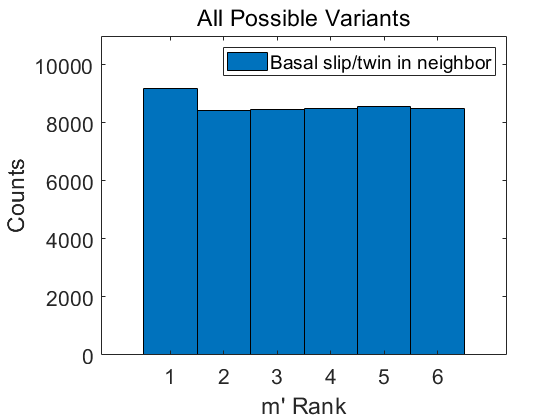


% Look at all possible variants, with basal/twin in neighbor   
N5 = histcounts(TT.rank_mPrime, edges);
figure; disableDefaultInteractivity(gca);  
bar(xpos, [N5(:)], 1, 'stacked');
legend({'Basal slip/twin in neighbor'},'location','northeast');
set(gca,'fontsize',16,'ylim',[0,11000]);
xlabel('m'' Rank');
ylabel('Counts');
title('All Possible Variants','fontweight','normal');

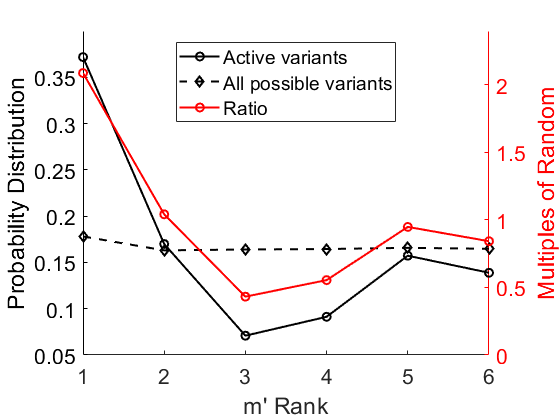


pmf_all = N5./sum(N5);

% (8) relative strength, slip/twin in neighbor
figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_all_exp, '-ko','linewidth',1.5);
plot(xpos, pmf_all, '--kd','linewidth',1.5);
ylabel('Probability Distribution');
yyaxis right;
plot(xpos, pmf_all_exp./pmf_all, '-ro','linewidth',1.5);
set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1]);
ylabel('Multiples of Random');
xlabel('m'' Rank');
set(gca,'fontsize',16);
legend({'Active variants','All possible variants','Ratio'},'location','north');
title('Twin in neighbor', 'fontweight','normal');
title('');

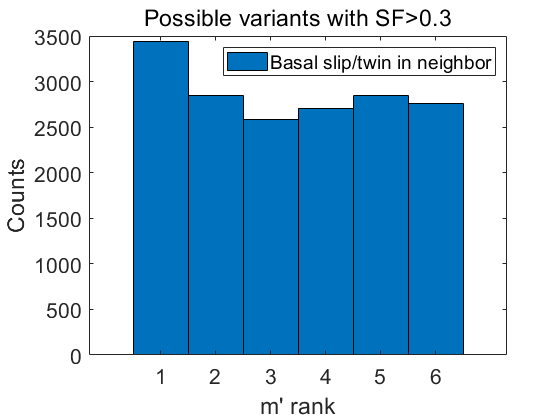

% ((())) If only select the twin system of interest with SF > 0.3
% For mPrime with both TorB in neighbor, there were already some assumptions, such as SF>0.2, SF_normalized>0.8, exist before twin of interest.
% ind = (TT.TSF>0.3)&((TT.iiE_twins_at_this_boundary_nb<TT.iiE_each_twin_at_this_boundary)|(TT.iiE_twins_at_this_boundary_nb==inf));   
ind = (T2.TSF>0.3);   % If we select possible twin systems to be with TSF > 0.3.
tt = [T;T2(ind,:)];

N6 = histcounts(tt.rank_mPrime, edges);
figure; disableDefaultInteractivity(gca);  
bar(xpos, [N6(:)], 1, 'stacked');
legend({'Basal slip/twin in neighbor'},'location','northeast');
set(gca,'fontsize',16);
xlabel('m'' rank');
ylabel('Counts');
title('Possible variants with SF>0.3','fontweight','normal');

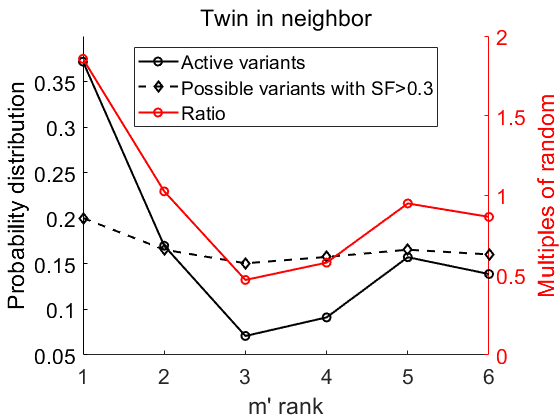


pmf_all_r = N6./sum(N6);    % restricted

% (8) relative strength, slip/twin in neighbor
figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_all_exp, '-ko','linewidth',1.5);
plot(xpos, pmf_all_r, '--kd','linewidth',1.5);
ylabel('Probability distribution');
yyaxis right;
plot(xpos, pmf_all_exp./pmf_all_r, '-ro','linewidth',1.5);
set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1]);
ylabel('Multiples of random');
xlabel('m'' rank');
set(gca,'fontsize',16);
legend({'Active variants','Possible variants with SF>0.3','Ratio'},'location','north');
title('Twin in neighbor', 'fontweight','normal');

**(III) Effect of residual Burgers vector (RBV)**

disp('(1) Effect of rbv ===============');

(1) Effect of rbv ===============


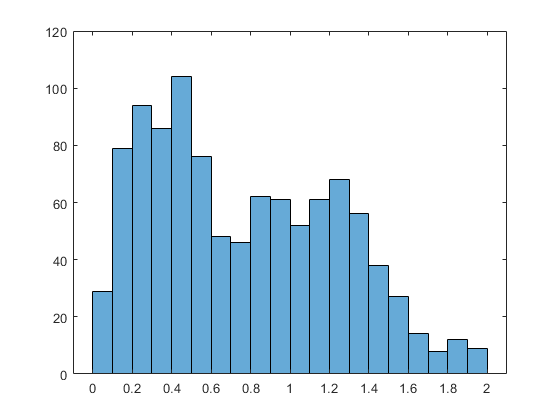

close all;
edges = [0:0.1:2];
edges(end) = edges(end)+ 1000*eps;
xpos = edges(1:end-1) + (edges(2)-edges(1))/2;

ind = (T.iiE_each_twin_at_this_boundary == T.iiE_each_twin)&(T.iiE_each_twin<=iE); 
t = T(ind,:);
figure; disableDefaultInteractivity(gca);
histogram(t.resB,20);

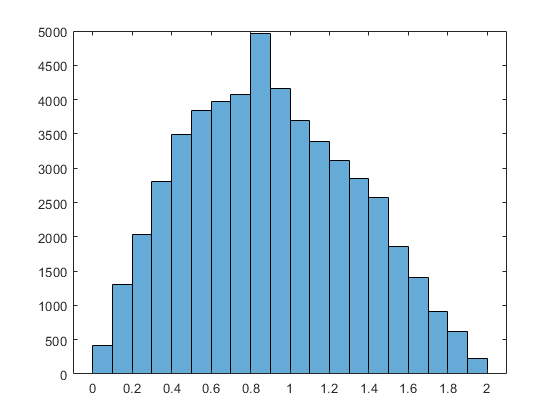

N = histcounts(t.resB, edges);
pmf_exp = N./sum(N);

tt = [T;T2];
figure; disableDefaultInteractivity(gca);
histogram(tt.resB,20);

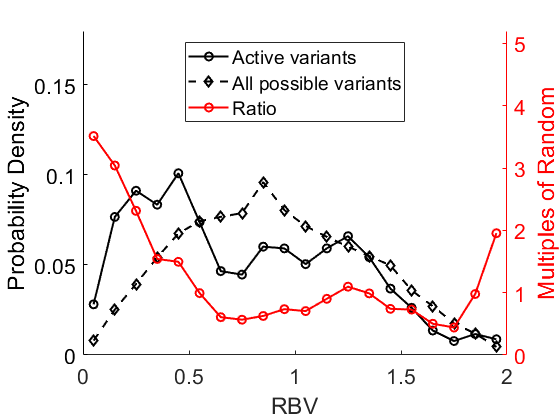

N3 = histcounts(tt.resB, edges);
pmf_r = N3./sum(N3);    % theoretical and restricted

figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_exp, '-ko','linewidth',1.5);
plot(xpos, pmf_r, '--kd','linewidth',1.5);
set(gca,'ylim',get(gca,'ylim').*[0,1.5]);
ylabel('Probability Density');
yyaxis right;
plot(xpos, pmf_exp./pmf_r, '-ro','linewidth',1.5);
set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1.3]);
ylabel('Multiples of Random');
xlabel('RBV');
set(gca,'fontsize',16);
legend({'Active variants','All possible variants','Ratio'},'location','north');
title('Slip/twin in neighbor', 'fontweight','normal');
title('');

** (IV) Effect of rank_ResB, has a little bit correlation, less than resB**

disp('(1) Effect of rbv_rank ===============');

(1) Effect of rbv_rank ===============


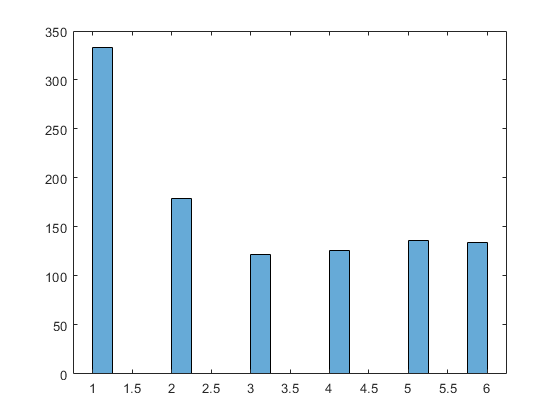

edges = [0.5:6.5];
edges(end) = edges(end)+ 1000*eps;
xpos = edges(1:end-1) + (edges(2)-edges(1))/2;

ind = (T.iiE_each_twin_at_this_boundary == T.iiE_each_twin)&(T.iiE_each_twin<=iE); 
t = T(ind,:);
figure; disableDefaultInteractivity(gca);
histogram(t.rank_resB,20);

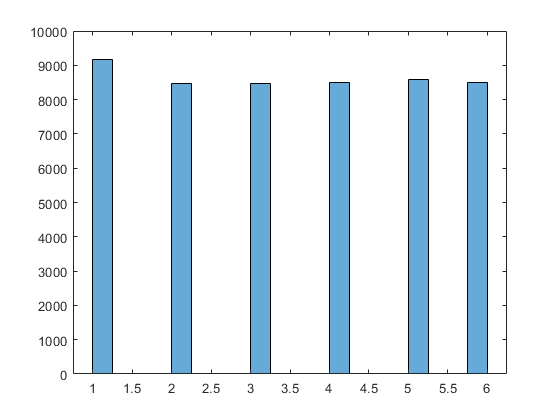

N = histcounts(t.rank_resB, edges);
pmf_exp = N./sum(N);

% ind = (T2.TSF>0.3);   % If we select possible twin systems to be with TSF > 0.3.
tt = [T;T2];    %(ind,:)];
figure; disableDefaultInteractivity(gca);
histogram(tt.rank_resB,20);

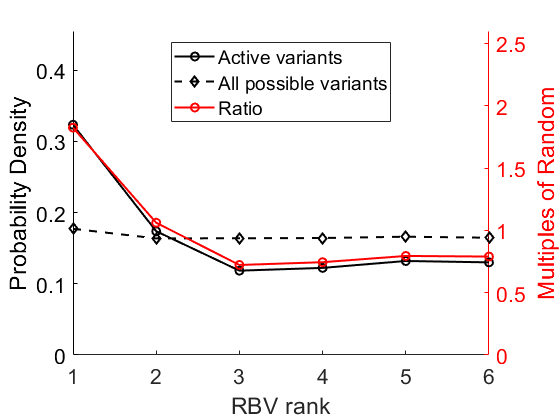

N3 = histcounts(tt.rank_resB, edges);
pmf_r = N3./sum(N3);    % theoretical and restricted

figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_exp, '-ko','linewidth',1.5);
plot(xpos, pmf_r, '--kd','linewidth',1.5);
set(gca,'ylim',get(gca,'ylim').*[0,1.3]);
ylabel('Probability Density');
yyaxis right;
plot(xpos, pmf_exp./pmf_r, '-ro','linewidth',1.5);
set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1.3]);
ylabel('Multiples of Random');
xlabel('RBV rank');
set(gca,'fontsize',16);
legend({'Active variants','All possible variants','Ratio'},'location','north');
title('Slip/twin in neighbor', 'fontweight','normal');
title('');

**(V) Effect of exz_ba. exz_ba has the most influence.**

**Effect of tGbStrength has not shown significant dependence yet.**

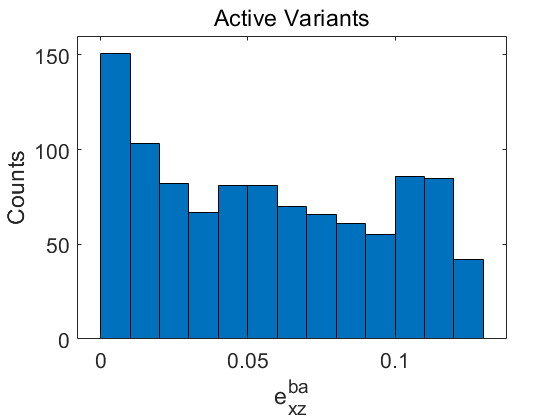

edges = [0:0.01:0.13];
edges(end) = edges(end)+ 1000*eps;
xpos = edges(1:end-1) + (edges(2)-edges(1))/2;

% active variants
ind = (T.iiE_each_twin_at_this_boundary == T.iiE_each_twin)&(T.iiE_each_twin<=iE); 
t = T(ind,:);
N_ba_exp = histcounts(t.exz_ba, edges);
N_pr_exp = histcounts(t.exz_pr, edges);
N_py_exp = histcounts(t.exz_py, edges);
N_pyII_exp = histcounts(t.exz_pyII, edges);
N_etw_exp = histcounts(t.exz_etw, edges);
% all possible variants
tt = [T;T2];    
N_ba_all = histcounts(tt.exz_ba, edges);
N_pr_all = histcounts(tt.exz_pr, edges);
N_py_all = histcounts(tt.exz_py, edges);
N_pyII_all = histcounts(tt.exz_pyII, edges);
N_etw_all = histcounts(tt.exz_etw, edges);


figure; disableDefaultInteractivity(gca);
bar(xpos, [N_ba_exp(:)], 1);
% legend({'Basal slip/twin in neighbor'},'location','best');
set(gca,'fontsize',16,'ylim',[0 160]);
xlabel('e_{xz}^{ba}');
ylabel('Counts');
title('Active Variants','fontweight','normal');

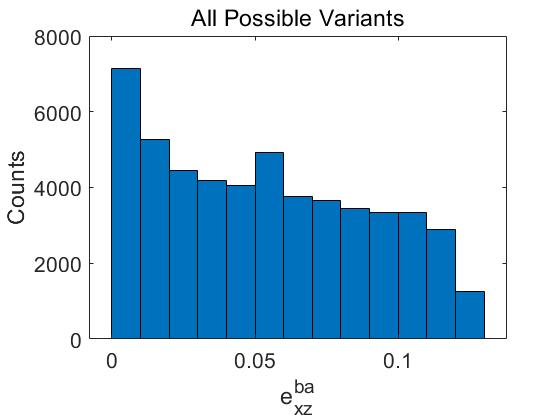

pmf_exp = N_ba_exp./sum(N_ba_exp);

figure; disableDefaultInteractivity(gca);
bar(xpos, [N_ba_all(:)], 1, 'stacked');
% legend({'Basal slip/twin in neighbor'},'location','best');
set(gca,'fontsize',16);
xlabel('e_{xz}^{ba}');
ylabel('Counts');
title('All Possible Variants','fontweight','normal');

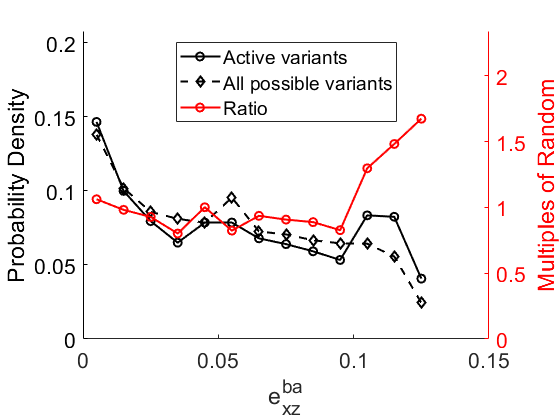

pmf_all = N_ba_all./sum(N_ba_all);    % theoretical and restricted

% ratio
figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_exp, '-ko','linewidth',1.5);
plot(xpos, pmf_all, '--kd','linewidth',1.5);
set(gca,'ylim',get(gca,'ylim').*[0,1.3]);
ylabel('Probability Density');
yyaxis right;
plot(xpos, pmf_exp./pmf_all, '-ro','linewidth',1.5);
set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1.3]);
ylabel('Multiples of Random');
xlabel('e_{xz}^{ba}');
set(gca,'fontsize',16);
legend({'Active variants','All possible variants','Ratio'},'location','north');
title('Slip/twin in neighbor', 'fontweight','normal');
title('');

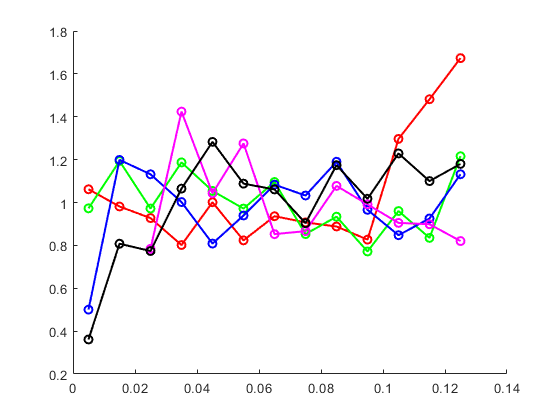



% all ratio
pmf_ba_exp = N_ba_exp./sum(N_ba_exp);
pmf_ba_all = N_ba_all./sum(N_ba_all); 
pmf_pr_exp = N_pr_exp./sum(N_pr_exp);
pmf_pr_all = N_pr_all./sum(N_pr_all); 
pmf_py_exp = N_py_exp./sum(N_py_exp);
pmf_py_all = N_py_all./sum(N_py_all); 
pmf_pyII_exp = N_pyII_exp./sum(N_pyII_exp);
pmf_pyII_all = N_pyII_all./sum(N_pyII_all); 
pmf_etw_exp = N_etw_exp./sum(N_etw_exp);
pmf_etw_all = N_etw_all./sum(N_etw_all); 
figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_ba_exp./pmf_ba_all, '-ro','linewidth',1.5);
plot(xpos, pmf_pr_exp./pmf_pr_all, '-go','linewidth',1.5);
plot(xpos, pmf_py_exp./pmf_py_all, '-bo','linewidth',1.5);
plot(xpos, pmf_pyII_exp./pmf_pyII_all, '-mo','linewidth',1.5);
plot(xpos, pmf_etw_exp./pmf_etw_all, '-ko','linewidth',1.5);

**Effect of exzr, such as exzr_etw.  Almost no effect**

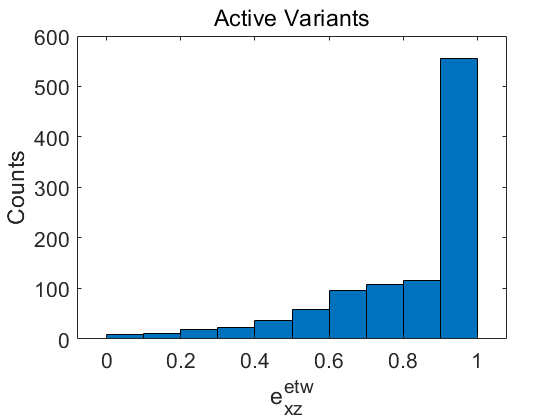

edges = [0:0.1:1];
edges(end) = edges(end)+ 1000*eps;
xpos = edges(1:end-1) + (edges(2)-edges(1))/2;

% active variants
ind = (T.iiE_each_twin_at_this_boundary == T.iiE_each_twin)&(T.iiE_each_twin<=iE); 
t = T(ind,:);
Nr_ba_exp = histcounts(t.exzr_ba, edges);
Nr_pr_exp = histcounts(t.exzr_pr, edges);
Nr_py_exp = histcounts(t.exzr_py, edges);
Nr_pyII_exp = histcounts(t.exzr_pyII, edges);
Nr_etw_exp = histcounts(t.exzr_etw, edges);
% all possible variants
tt = [T;T2];    
Nr_ba_all = histcounts(tt.exzr_ba, edges);
Nr_pr_all = histcounts(tt.exzr_pr, edges);
Nr_py_all = histcounts(tt.exzr_py, edges);
Nr_pyII_all = histcounts(tt.exzr_pyII, edges);
Nr_etw_all = histcounts(tt.exzr_etw, edges);


figure; disableDefaultInteractivity(gca);
bar(xpos, [Nr_etw_exp(:)], 1);
set(gca,'fontsize',16);
xlabel('e_{xz}^{etw}');
ylabel('Counts');
title('Active Variants','fontweight','normal');

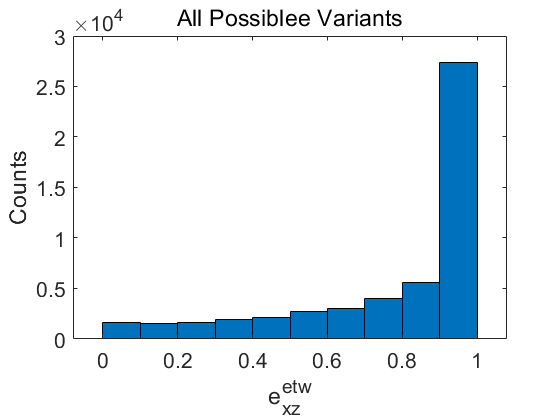

pmf_exp = Nr_etw_exp./sum(Nr_etw_exp);

figure; disableDefaultInteractivity(gca);
bar(xpos, [Nr_etw_all(:)], 1, 'stacked');
set(gca,'fontsize',16);
xlabel('e_{xz}^{etw}');
ylabel('Counts');
title('All Possiblee Variants','fontweight','normal');

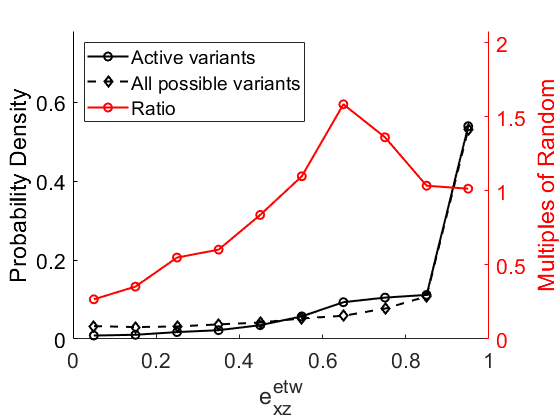

pmf_all = Nr_etw_all./sum(Nr_etw_all);    % theoretical and restricted

% ratio
figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_exp, '-ko','linewidth',1.5);
plot(xpos, pmf_all, '--kd','linewidth',1.5);
set(gca,'ylim',get(gca,'ylim').*[0,1.3]);
ylabel('Probability Density');
yyaxis right;
plot(xpos, pmf_exp./pmf_all, '-ro','linewidth',1.5);
set(gca,'ycolor','r', 'ylim',get(gca,'ylim').*[0,1.3]);
ylabel('Multiples of Random');
xlabel('e_{xz}^{etw}');
set(gca,'fontsize',16);
legend({'Active variants','All possible variants','Ratio'},'location','northwest');
title('Slip/twin in neighbor', 'fontweight','normal');
title('');

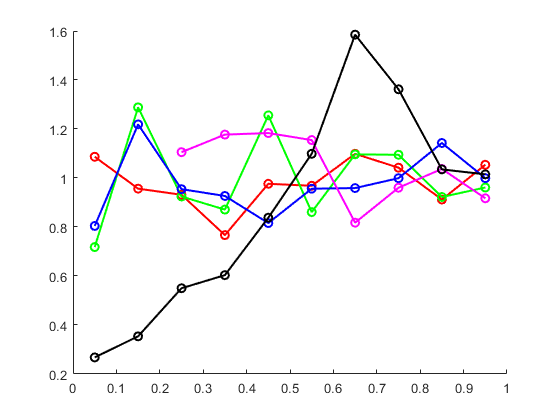



% all ratio
pmf_ba_exp = Nr_ba_exp./sum(Nr_ba_exp);
pmf_ba_all = Nr_ba_all./sum(Nr_ba_all); 
pmf_pr_exp = Nr_pr_exp./sum(Nr_pr_exp);
pmf_pr_all = Nr_pr_all./sum(Nr_pr_all); 
pmf_py_exp = Nr_py_exp./sum(Nr_py_exp);
pmf_py_all = Nr_py_all./sum(Nr_py_all); 
pmf_pyII_exp = Nr_pyII_exp./sum(Nr_pyII_exp);
pmf_pyII_all = Nr_pyII_all./sum(Nr_pyII_all); 
pmf_etw_exp = Nr_etw_exp./sum(Nr_etw_exp);
pmf_etw_all = Nr_etw_all./sum(Nr_etw_all); 
figure; disableDefaultInteractivity(gca); hold on;
plot(xpos, pmf_ba_exp./pmf_ba_all, '-ro','linewidth',1.5);
plot(xpos, pmf_pr_exp./pmf_pr_all, '-go','linewidth',1.5);
plot(xpos, pmf_py_exp./pmf_py_all, '-bo','linewidth',1.5);
plot(xpos, pmf_pyII_exp./pmf_pyII_all, '-mo','linewidth',1.5);
plot(xpos, pmf_etw_exp./pmf_etw_all, '-ko','linewidth',1.5);

## This shows the relationship between m' rank and resB rank.

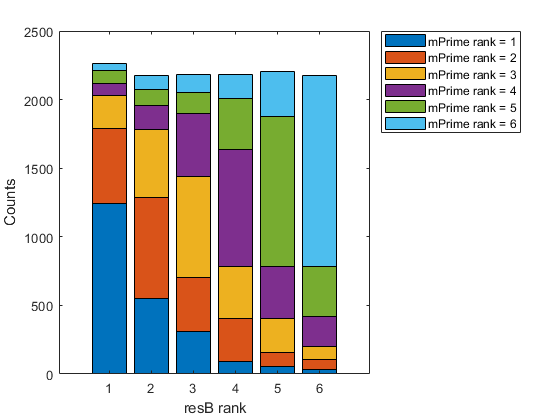

close all;
colormap parula
edges = 0.5:6.5;
N = zeros(6,6);
for ii = 1:6
    ind = (T.rank_mPrime == ii);
    [N(:,ii),~] = histcounts(T.rank_resB(ind), edges);
end
figure;
bar(1:6, N, 'stacked');
xlabel('resB rank');
ylabel('Counts');
legend({'mPrime rank = 1','mPrime rank = 2','mPrime rank = 3','mPrime rank = 4','mPrime rank = 5','mPrime rank = 6'},'location','bestoutside');

## (5) m' vs neighbor_SF